# Using simulink to support the study of state space systems: Part 3

The control101 toolbox focuses mainly on linear models and thus simple MATLAB code is sufficient to illustrate the core behaviours. However, the real world is full of non-linear components and characteristics such as saturations, switches and non-simple shapes. In such cases non-linear models are needed and simulink is an ideal tool to capture this. 

The study of state space systems requires operations which are often most easily represented with block diagrams, that is simulink, rather than the precise algebra required in MATLAB m-files. This sequence of files demonstrates some simple simulink files for supporting such studies, which also can be extended easily to add non-linear components.

The previous files introduced simulation with state space models, state feedback and observers but in all cases it became clear that the simple solutions are robutness to any form of uncertainty. In general, in order to reject uncertainty and ensure offset free tracking, integral actions is needed. This file shows how such integral action can be embedded into suitable simulink models.

 Logically this follows on from the introduction files on state space systems with simulink: ***state_space_and_simulinkfile1_control101, state_space_and_simulinkfile2_control101.***

The simulink files were made with MATLAB 2023b so may not work with earlier versions of MATLAB.

### Similar files and the toolbox

See website below for more files like this.  

[https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

### **Background on simulink**

The state space sequence does not focus on teaching simulink, but assumes familiarity and just uses the tool. Readers will be aware that there are number of settings in a simulink file, for example to define the format of input and output data. The settings and code snippets below work together, so if you change any of these settings then the code may need minor changes. A number of introductory files on simulink are available as listed next.

*myfirstsimulink_control101, intro_to_simulink_for_system_behaviour, car_suspension_simulink_control101, heating_system_simulink_control101, position_system_simulink_control101, hydraulic_system_simulink_control101, submersible_simulink_control101  *      

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Introduction to the use of simulink with observers

- Simulation with initial state estimation error and zero target (nominal case)

- Simulation with non-zero zero target and disturbances (nominal case)

- Simulation with parameterisations errors, initial state estimation errors and disturbances.

## 1. Introduction to the use of simulink with observers

This file follows on from ***state_space_and_simulinkfile2_control101***, so it is assumed that readers are familiar with the content of that.

### 1.1. Introductory background

Here assume a state space model of the form:

$\dot{X} =A\;X+B\;U;\;Y=C\;X+d,\;$ (1.1)

with state *X*, input *U* and output *Y. * In place of the actual states  *X*, we will need to use estimates *Z* for those values. The estimator and controller are summarised in the following: 


$$\dot{Z} =\left\lbrack A_m -L{\;\mathrm{C}}_m \right\rbrack \;Z+{\left\lbrack \begin{array}{cc}
B_m  & L
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
U\\
Y
\end{array}\right\rbrack } ;{\;\;\;\;Y}_m =C_m Z,\;U=-K\;Z+P\;r,\;\;\;P=-\;{\left(C_m {\left\lbrack A_m -B_m \;K\right\rbrack }^{-1} B_m \right)}^{-1} \;\;\;\;\;\;\left(1\ldotp 2\right)$$


For more on observers and tracking see the files: ***tracking_with_statespace_control101, observer_design_control101***.

Nevertheless, it was clear from the previous file that such a solution cannot deal with uncertainty, that is non-zero output disturbances *d* and parameter errors:  $A_m \not= A,B_m \not= B,C_m \not= C$. Hence integral actions is required. Suitable mechanisms for this are in the tracking file: ***tracking_with_statespace_control101.***

### 1.2 Including integral action into a state space feedback design

A simple method used in traditional control to remove steady-state offset is to to include the integral of the error within the feedback law. Hence, the proposal here is to create a new state/s in the state space model to capture this term, that is:


$$\frac{d\;Z}{d\;t}=r-C\;X$$


Next ensure that the state feedback depends upon this new state *Z*, and indeed ensure that the state feedback is driving *Z* to a constant, which implies the offset must be zero. Hence, the augmented system model becomes:


$$\left\lbrace \left\lbrack \begin{array}{c}
\dot{X} \\
\dot{Z} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
A & 0\\
-C & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
B\\
0
\end{array}\right\rbrack U+\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r\right\rbrace \;\;\;\Rightarrow \;\left\lbrace \dot{W} =A_{\textrm{aug}} W+B_{\textrm{aug}} U+\left\lbrack \begin{array}{c}
0\\
I
\end{array}\right\rbrack r;\;W=\left\lbrack \begin{array}{c}
X\\
Z
\end{array}\right\rbrack \right\rbrace \;\;\;\;\;\;\;\;\;\;\left(1\ldotp 3\right)$$


In the first instance, find a stabilising state feedback of the form:  $U=-K\;W$ for the augmented system and note that in practice this should be modified to:


$$U=-K\;W+P\;r;\;\;P={\left(C_m {\left\lbrack A_m -B_m \;K\right\rbrack }^{-1} B_m \right)}^{-1} \;\;\;\;\;\;\;\left(1\ldotp 4\right)$$


This file will demonstrate how a simulink model encompassing the models/control statements of (1.1 - 1.4). The appropriate diagram is given in Figure 1 below.

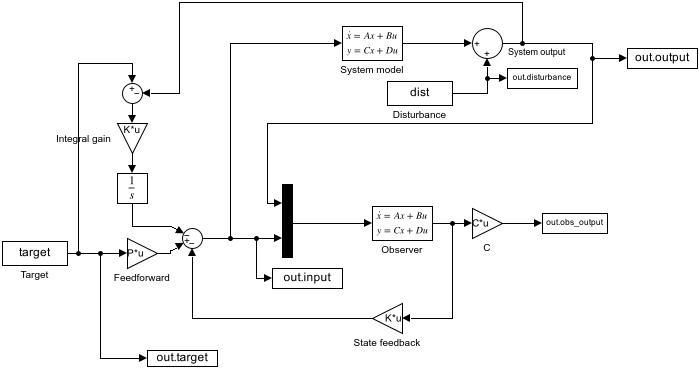

**Figure 1**: Screen plot of supporting simulink model: ***state_space_simulink_integral_control101.slx***

## 2. Integral action in the nominal case

The code here shows how one can easily construct the augmented models and state feedback terms (eqn. 1.1-1.4)  and closed-loop systems to demonstrate the impact of integral action in a state space system.  For now this section assumes no parameter uncertainty and no disturbances to demonstrate the simplest case.

disp('Section 2 below')

Section 2 below


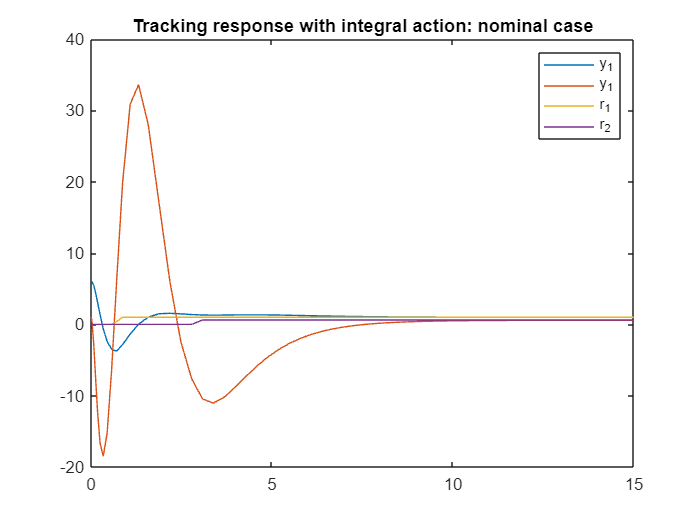

% Real process - values used in simulink simulation
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D=zeros(2,2);

% model - nominal case
Am=A;Bm=B;Cm=C;

% Augmented model to find state fbk - include error states
Aaug = [Am,zeros(4,2);-Cm,zeros(2,2)];
Baug = [Bm;zeros(2,2)];
Caug = [Cm,zeros(2,2)];
Daug = zeros(2,2);

% Observer implementation 
deseig_ob = [-2+0.4i,-2-0.4i,-4 -6];
L = place(Am',Cm',deseig_ob); % 
L = L';
Aob = Am-L*Cm; Bob = [L,Bm]; Cob = eye(4); Dob = zeros(4,4);

% Control design
Qaug = [C'*C,zeros(4,2);zeros(2,4),eye(2)]; 
Raug=eye(2);
Kaug=lqr(Aaug,Baug,Qaug,Raug);
Kx = Kaug(:,1:4);  % state fbk
Ke = Kaug(:,5:6);   % integral of error fbk
P = -inv(Cm*inv(Am-Bm*Kx)*Bm);

% input signal characterisation
endtime=15;
dist.time = linspace(0,endtime,200);
dist.signals.values = 0* [[zeros(120,1);ones(80,1)*0.2],[zeros(140,1);ones(60,1)*(-0.1)]];
dist.signals.dimensions = 2;
target.time = dist.time;
target.signals.values = [[zeros(10,1);ones(190,1)*1],[zeros(40,1);ones(160,1)*0.6]];
target.signals.dimensions = 2;

% simulation
Data= sim('state_space_simulink_integral_control101.slx');
y=Data.output.signals;          % system output
d=Data.disturbance.signals;     % disturbance signal
r=Data.target.signals;          % target
y_o = Data.obs_output.signals; % observer output
u = Data.input.signals;        % input

% Plotting
plot(Data.tout,y.values,Data.tout,r.values)
legend('y_1','y_1','r_1','r_2')
title('Tracking response with integral action: nominal case')


%print(['-sstate_space_simulink_integral_control101'],'-djpeg',['state_space_simulink_integral_control101.jpg'])

## 3. Simulation with non-zero zero target and disturbances (nominal case)

This section introduces some uncertainty and specifically the output disturbance but with no parameterisation errors. The code below lays out the data required for the simulink file, collects the output and creates some plots. Clearly this can be modified as required by readers.

The figures show that irrespective of the uncertainty (assuming closed-loop stability), offset free tracking is achieved. It is worth remarking that the model used here has 2 RHP poles in the open-loop and thus is challenging which will explain the difficult behaviour during transients. Some more straightforward examples are in section 4.

disp('Section 3: Responses with uncertainty')

Section 3: Responses with uncertainty


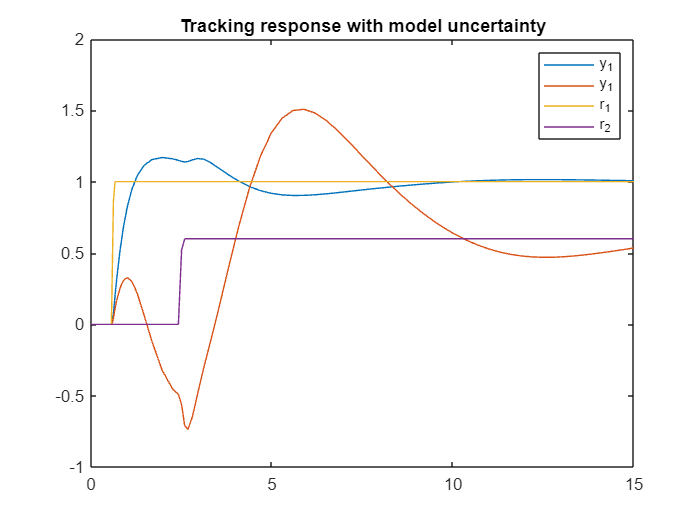


% Real process model
A=[-0. -0.4 -0.6 0.2;0.4 1 .7 .5;-0.3 1 1 0;0.8 1.1 -0.3 0]; 
B=[1 0;-1 1;0 0.3;-1 2];
C=[3 2 1 0;0 0 0 1];
D=zeros(2,2);
x0=[0;0;0;0];

% model - values used in observer and controller design
Am=[-0. -0.4 -0.6 0.21;0.4 1 .7 .5;-0.3 1.0 1 0;0.8 1.1 -0.3 0]; 
Bm=[1 0;-1 1;0 0.3;-1 1.9];
Cm=[3.2 2 1.1 0;0 0 0 1];
Dm = zeros(2,2);

% Augmented model to find state fbk - include error states
Aaug = [Am,zeros(4,2);-Cm,zeros(2,2)];
Baug = [Bm;zeros(2,2)];
Caug = [Cm,zeros(2,2)];
Daug = zeros(2,2);

% Observer implementation 
deseig_ob = [-2+0.4i,-2-0.4i,-4 -6];
L = place(Am',Cm',deseig_ob); % 
L = L';
Aob = Am-L*Cm; Bob = [L,Bm]; Cob = eye(4); Dob = zeros(4,4);

% Control design
Qaug = [C'*C,zeros(4,2);zeros(2,4),eye(2)]; 
Raug=eye(2);
Kaug=lqr(Aaug,Baug,Qaug,Raug);
Kx = Kaug(:,1:4);  % state fbk
Ke = Kaug(:,5:6);   % integral of error fbk
P = -inv(Cm*inv(Am-Bm*Kx)*Bm);

% input signal characterisation
endtime=15;
dist.time = linspace(0,endtime,240);
dist.signals.values = [[zeros(120,1);ones(120,1)*0.2],[zeros(140,1);ones(100,1)*(-0.1)]];
dist.signals.dimensions = 2;
target.time = dist.time;
target.signals.values = [[zeros(10,1);ones(230,1)*1],[zeros(40,1);ones(200,1)*0.6]];
target.signals.dimensions = 2;

% tracking errors
dist.signals.values=dist.signals.values*0;
Data1= sim('state_space_simulink_integral_control101.slx');
% Disturbance rejection
target.signals.values = 0*target.signals.values;
dist.signals.values =  [[zeros(20,1);ones(220,1)*0.2],[zeros(100,1);ones(140,1)*(-0.1)]];
Data2= sim('state_space_simulink_integral_control101.slx');

% Plotting for tracking example
y=Data1.output.signals;          % system output
d=Data1.disturbance.signals;     % disturbance signal
r=Data1.target.signals;          % target
y_o = Data1.obs_output.signals; % observer output
u = Data1.input.signals;        % input
plot(Data1.tout,y.values,Data1.tout,r.values)
legend('y_1','y_2','r_1','r_2')
title('Tracking response with model uncertainty')

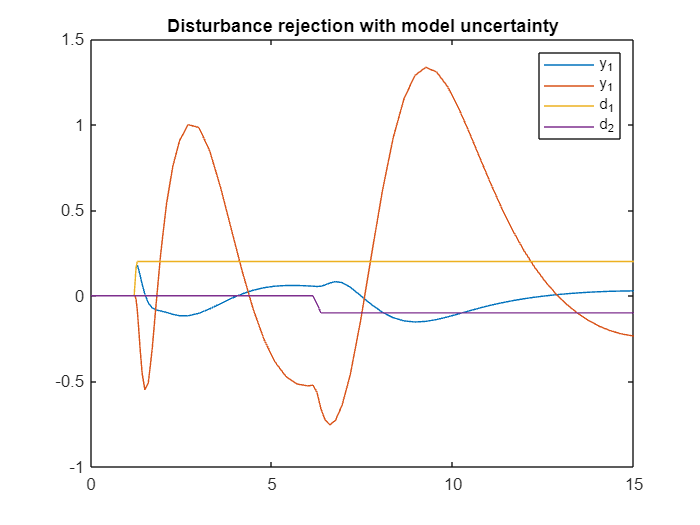


% Plotting for disturbance rejection example
y=Data2.output.signals;
d=Data2.disturbance.signals;
plot(Data2.tout,y.values,Data2.tout,d.values)
legend('y_1','y_2','d_1','d_2')
title('Disturbance rejection with model uncertainty')

## 3. Simulations with simple case studies

This section uses some simpler examples so that raders can explore particular issues more easily but otherwise has the same messaging as previous section. Readers are encouraged to enter their own models and design choices. Using the code provided as templates.

disp('Section 4: Miscellaneous examples')

Section 4: Miscellaneous examples


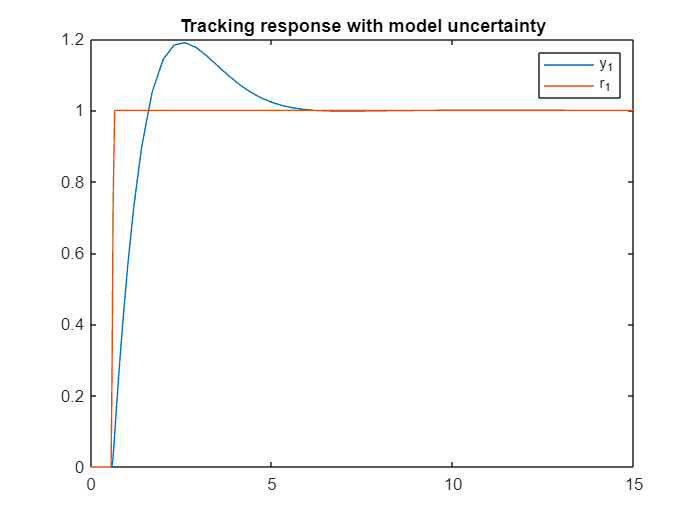


% Real process model
A = [0 1; -0.4 -1]; 
B = [1; 0]; 
C = [1 0]; D = 0;
D=zeros(2,2);
x0=[0;0];

% System model
Am = [0 1; -0.43 -1]; 
Bm = [1.1; 0]; 
Cm = [1 0]; D = 0;
Dm = 0;

% Augmented model to find state fbk - include error states
Aaug = [Am,zeros(2,1);-Cm,zeros(1,1)];
Baug = [Bm;zeros(1,1)];
Caug = [Cm,zeros(1,1)];
Daug = zeros(1,1);

% Observer implementation 
deseig_ob = [-4 -6];
L = place(Am',Cm',deseig_ob); % 
L = L';
Aob = Am-L*Cm; Bob = [L,Bm]; Cob = eye(2); Dob = zeros(2,2);

% Control design
Qaug = [C'*C,zeros(2,1);zeros(1,2),eye(1)]; 
Raug=eye(1);
Kaug=lqr(Aaug,Baug,Qaug,Raug);
Kx = Kaug(:,1:2);  % state fbk
Ke = Kaug(:,3);   % integral of error fbk
P = -inv(Cm*inv(Am-Bm*Kx)*Bm);

% input signal characterisation
endtime=15;
dist.time = linspace(0,endtime,240);
dist.signals.values = [zeros(120,1);ones(120,1)*0.2];
dist.signals.dimensions = 1;
target.time = dist.time;
target.signals.values = [zeros(10,1);ones(230,1)*1];
target.signals.dimensions = 1;

% tracking errors
dist.signals.values=dist.signals.values*0;
Data1= sim('state_space_simulink_integral_control101.slx');
% Disturbance rejection
target.signals.values = 0*target.signals.values;
dist.signals.values =  [zeros(20,1);ones(220,1)*0.2];
Data2= sim('state_space_simulink_integral_control101.slx');

% Plotting for tracking example
y=Data1.output.signals;          % system output
d=Data1.disturbance.signals;     % disturbance signal
r=Data1.target.signals;          % target
y_o = Data1.obs_output.signals; % observer output
u = Data1.input.signals;        % input
plot(Data1.tout,y.values,Data1.tout,r.values)
legend('y_1','r_1')
title('Tracking response with model uncertainty')

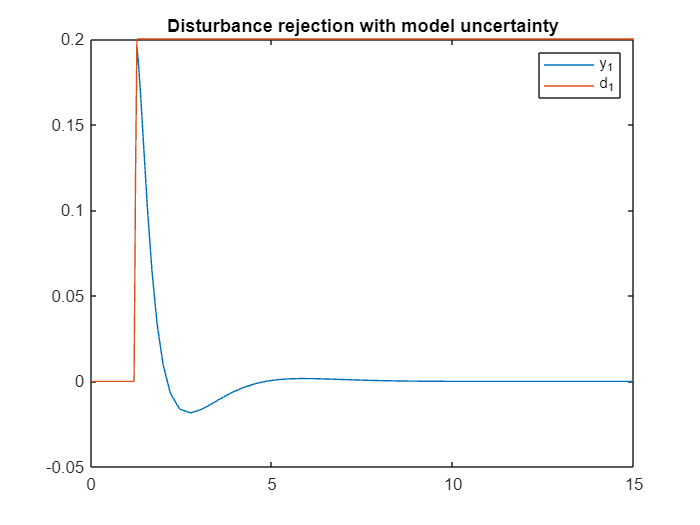


% Plotting for disturbance rejection example
y=Data2.output.signals;
d=Data2.disturbance.signals;
plot(Data2.tout,y.values,Data2.tout,d.values)
legend('y_1','d_1')
title('Disturbance rejection with model uncertainty')